# Part I: Histogram and entropy

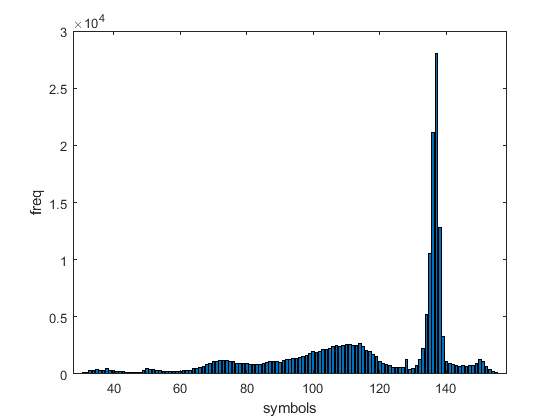

symbol-->probability


  '29' --> 5.0863e-06
  '30' --> 0.00019328
  '31' --> 0.00050863
  '32' --> 0.00082906
  '33' --> 0.0015055
  '34' --> 0.0015767
  '35' --> 0.0021973
  '36' --> 0.0017497
  '37' --> 0.0017242
  '38' --> 0.0023092
  '39' --> 0.0015004
  '40' --> 0.0014648
  '41' --> 0.0011902
  '42' --> 0.0011495
  '43' --> 0.0009257
  '44' --> 0.0008138
  '45' --> 0.00084941
  '46' --> 0.00068665
  '47' --> 0.00077311
  '48' --> 0.00082397
  '49' --> 0.0016683
  '50' --> 0.0024261
  '51' --> 0.002065
  '52' --> 0.0021667
  '53' --> 0.0015513
  '54' --> 0.0013377
  '55' --> 0.001241
  '56' --> 0.0010783
  '57' --> 0.00095113
  '58' --> 0.001119
  '59' --> 0.0010681
  '60' --> 0.0011648
  '61' --> 0.0014191
  '62' --> 0.001358
  '63' --> 0.001531
  '64' --> 0.002299
  '65' --> 0.0023549
  '66' --> 0.0028788
  '67' --> 0.0034078
  '68' --> 0.0042572
  '69' --> 0.0047302
  '70' --> 0.0056101
  '71' --> 0.0056559
  '72' --> 0.0060425
  '73' --> 0.00619
  '74' --> 0.0058695
  '75' --> 0.0057322
  '76' --> 0

the entropy of this file (bit per unit): 5.7535


the compression ratio compared to 8 bpu: 273376.9421


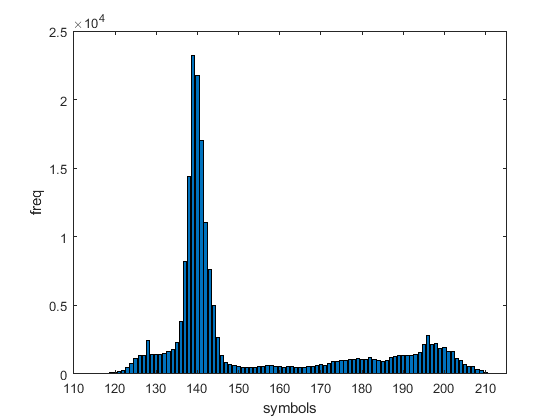

symbol-->probability


  '111' --> 5.0863e-06
  '112' --> 2.5431e-05
  '113' --> 0.00011698
  '114' --> 0.00017802
  '115' --> 0.00019836
  '116' --> 0.00016276
  '117' --> 0.00020345
  '118' --> 0.00025431
  '119' --> 0.00038147
  '120' --> 0.00054423
  '121' --> 0.00077311
  '122' --> 0.0012716
  '123' --> 0.0023855
  '124' --> 0.0040588
  '125' --> 0.0056864
  '126' --> 0.0068461
  '127' --> 0.0067952
  '128' --> 0.012604
  '129' --> 0.0071513
  '130' --> 0.0073191
  '131' --> 0.0071259
  '132' --> 0.0076701
  '133' --> 0.008194
  '134' --> 0.0091858
  '135' --> 0.011637
  '136' --> 0.019313
  '137' --> 0.041631
  '138' --> 0.073196
  '139' --> 0.118
  '140' --> 0.11082
  '141' --> 0.086533
  '142' --> 0.056015
  '143' --> 0.038783
  '144' --> 0.025218
  '145' --> 0.013433
  '146' --> 0.0067139
  '147' --> 0.0041911
  '148' --> 0.0035553
  '149' --> 0.0031942
  '150' --> 0.0026703
  '151' --> 0.0024363
  '152' --> 0.0023397
  '153' --> 0.0023804
  '154' --> 0.0024872
  '155' --> 0.0027669
  '156' --> 0.00

the entropy of this file (bit per unit): 5.3164


the compression ratio compared to 8 bpu: 295850.7465


clear all; close all; clc;
str = "HUFFMAN IS THE BEST COMPRESSION ALGORITHM";
imrgb = imread('./peppers_rgb.png');
imgray = imread('./peppers_gray.png');
X = imrgb;
if isa(X,'uint8') && size(X,3)==3 % color image input
    %convert RGB to YCbCr and only takes the CbCr
    imycbcr = rgb2ycbcr(X);
    y = imycbcr(:,:,1);
    cb = imycbcr(:,:,2);
    cr = imycbcr(:,:,3);
    figure(1);
    [sym_cb, freq_cb,entropy_cb,cr_cb] = myEntropy(cb);
    bar(sym_cb,freq_cb);xlabel('symbols');ylabel('freq'); 
    saveas(gcf,'./figures/cb_hist.png');
    disp(['symbol-->probability']);
    for i=1:numel(sym_cb)
       disp(['  ''',num2str(sym_cb(i)),''' --> ',num2str(transpose(freq_cb(i)/sum(freq_cb)))]); 
    end
    display(['the entropy of this file (bit per unit): ',num2str(entropy_cb)]);
    display(['the compression ratio compared to 8 bpu: ',num2str(cr_cb)]);
    [sym_cr, freq_cr,entropy_cr,cr_cr] = myEntropy(cr);
    figure(2);
    bar(sym_cr,freq_cr);xlabel('symbols');ylabel('freq'); 
    saveas(gcf,'./figures/cr_hist.png');
    disp(['symbol-->probability']);
    for i=1:numel(sym_cr)
       disp(['  ''',num2str(sym_cr(i)),''' --> ',num2str(transpose(freq_cr(i)/sum(freq_cr)))]); 
    end
    display(['the entropy of this file (bit per unit): ',num2str(entropy_cr)]);
    display(['the compression ratio compared to 8 bpu: ',num2str(cr_cr)]);
elseif isa(X,'uint8')
    [sym, freq,entropy,cr] = myEntropy(X);
    bar(sym,freq);xlabel('symbols');ylabel('freq'); 
    saveas(gcf,'./figures/gray_hist.png');
    disp(['symbol-->probability']);
    for i=1:numel(sym)
       disp(['  ''',num2str(sym(i)),''' --> ',num2str(transpose(freq(i)/sum(freq)))]); 
    end
    display(['the entropy of this file (bit per unit): ',num2str(entropy)]);
    display(['the compression ratio compared to 8 bpu: ',num2str(cr)]);
else
    [sym, freq,entropy,cr] = myEntropy(X);
    bar(freq); set(gca,'xticklabel',num2cell(char(sym)));
    title('String'); xlabel('symbols');ylabel('freq');
    saveas(gcf,'./figures/string_hist.png');
    disp(['symbol-->probability']);
    for i=1:numel(sym)
       disp(['  ''',char(sym(i)),''' --> ',num2str(transpose(freq(i)/sum(freq)))]); 
    end
    display(['the entropy of this file (bit per unit): ',num2str(entropy)]);
    display(['the compression ratio compared to 8 bpu: ',num2str(cr)]);
end 


% intensity historgram result of Cb is 0 to 160 vs Cr 120 to 210, both
% peaking at 140, these two chromacity values correspond to different
% ranges of intensity values

## Part II : Huffman encode and decode

clear all; close all; clc;
str = 'Thequickbrownfoxjumpsoverthelazydog';
codebook = HuffmanCompressionAlgorithm(char(str))

codebook = 35×2 cell array
    {'T'}    {'00110'}
    {'h'}    {'0000' }
    {'e'}    {'1110' }
    {'q'}    {'00111'}
    {'u'}    {'0001' }
    {'i'}    {'01000'}
    {'c'}    {'01001'}
    {'k'}    {'01010'}
    {'b'}    {'01011'}
    {'r'}    {'0010' }
    {'o'}    {'1111' }
    {'w'}    {'01100'}
    {'n'}    {'01101'}
    {'f'}    {'01110'}
    {'o'}    {'1111' }
    {'x'}    {'01111'}
    {'j'}    {'10000'}
    {'u'}    {'0001' }
    {'m'}    {'10001'}
    {'p'}    {'10010'}
    {'s'}    {'10011'}
    {'o'}    {'1111' }
    {'v'}    {'10100'}
    {'e'}    {'1110' }
    {'r'}    {'0010' }
    {'t'}    {'10101'}
    {'h'}    {'0000' }
    {'e'}    {'1110' }
    {'l'}    {'10110'}
    {'a'}    {'10111'}


sym_no = numel(codebook(:,2));
bit = 5;
sum = 0;
bitstr='';
for i=1:sym_no
    sum = sum + strlength(codebook(i,2));
    bitstr = strcat(bitstr,(codebook(i,2)));
end
bitstr = char(bitstr);

disp(['bitstream: ',bitstr]);

bitstream: 001100000111000111000101000010010101001011001011110110001101011101111011111000000011000110010100111111101001110001010101000011101011010111110001100111010111111011


disp(['sum bit of encoded message: ',num2str(sum)]);

sum bit of encoded message: 162


disp(['compare to ',num2str(bit),' bpu it takes to encode ',num2str(sym_no),' symbols: ',num2str(sym_no*bit)]);

compare to 5 bpu it takes to encode 35 symbols: 175


disp(['compression ratio: ',num2str(sym_no*bit/sum)]);

compression ratio: 1.0802



%Huffman decode
sym=transpose(codebook(:,1));
code=transpose(codebook(:,2));
codebook = table(sym',code');
codebook = unique(codebook);
codebook = table2array(codebook)

codebook = 27×2 cell array
    {'T'}    {'00110'}
    {'a'}    {'10111'}
    {'b'}    {'01011'}
    {'c'}    {'01001'}
    {'d'}    {'11010'}
    {'e'}    {'1110' }
    {'f'}    {'01110'}
    {'g'}    {'11011'}
    {'h'}    {'0000' }
    {'i'}    {'01000'}
    {'j'}    {'10000'}
    {'k'}    {'01010'}
    {'l'}    {'10110'}
    {'m'}    {'10001'}
    {'n'}    {'01101'}
    {'o'}    {'1111' }
    {'p'}    {'10010'}
    {'q'}    {'00111'}
    {'r'}    {'0010' }
    {'s'}    {'10011'}
    {'t'}    {'10101'}
    {'u'}    {'0001' }
    {'v'}    {'10100'}
    {'w'}    {'01100'}
    {'x'}    {'01111'}
    {'y'}    {'11001'}
    {'z'}    {'11000'}


sym=transpose(codebook(:,1));
code=transpose(codebook(:,2));

code_size=[];
sym_no=length(sym);
decoded='';
strlen=length(bitstr);
for i=1:sym_no
    l=length(char(code(i)));
    code_size=[code_size l];
end
max_code=max(code_size);
i=1;
while i<=strlen
    j=0;
    while j<max_code
        c=bitstr(i:i+j);
        index=1;
        while (index<=sym_no && ~isequal(char(code(index)),c))
            index=index+1;
        end
        if index<=sym_no
            decoded=[decoded char(sym(index))];
            break
        else j=j+1;
        end
    end
    i=i+j+1;
end
disp(['decoded message: ',decoded]);

decoded message: Thequickbrownfoxjumpsoverthelazydog
